# DSP Pipeline Analysis

Program to plot the outputs from the local processing on the SHARC Buoy. 

%Specify location of file
outdir_2 = "C:\Users\uctsh\Documents\MATLAB\PipelineData\FINALDATA";

%Specify variables
opts = delimitedTextImportOptions("NumVariables", 1);
opts.VariableNames = ["Heave"];
opts.VariableTypes = ["double"];

%Read in table
wavefile = fullfile(outdir_2, "SHARC_PSDAverage.txt");
WaveTable = readtable(wavefile, opts);

## Plot raw acceleration data

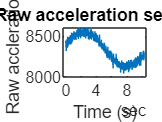

Fs = 100;
WaveTimeTable = table2timetable(WaveTable, 'SampleRate', Fs);
plot(WaveTimeTable.Time, WaveTimeTable.Heave);
xlabel("Time (s)");
ylabel("Raw accleration");
title("Raw acceleration segment");

## Plot scaled data

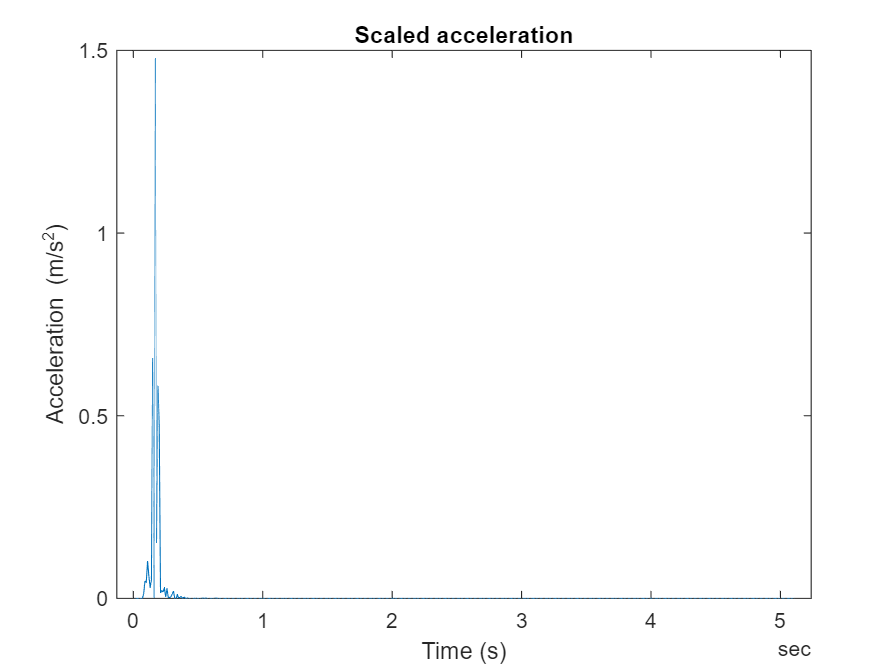

Fs = 100;
WaveTimeTable = table2timetable(WaveTable, 'SampleRate', Fs);
plot(WaveTimeTable.Time, WaveTimeTable.Heave);
xlabel("Time (s)");
ylabel("Acceleration (m/s^2)");
title("Scaled acceleration");

##  Plot detrended data

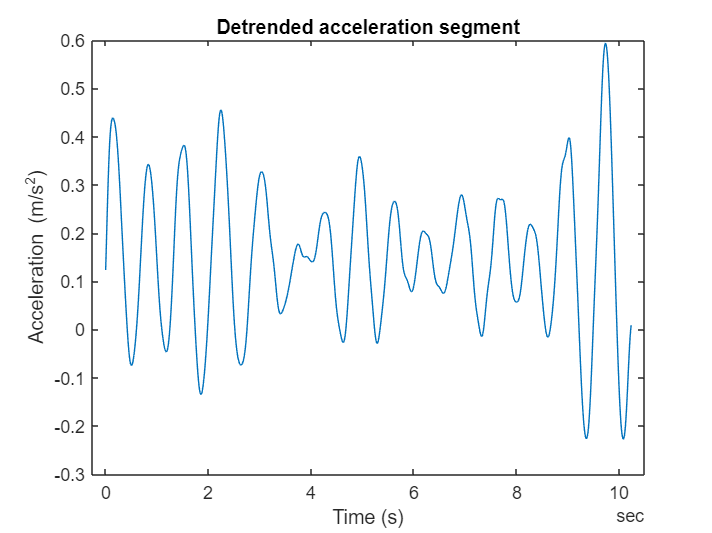

Fs = 100;
WaveTimeTable = table2timetable(WaveTable, 'SampleRate', Fs);
plot(WaveTimeTable.Time, lowpass(WaveTimeTable.Heave, 2, Fs));
xlabel("Time (s)");
ylabel("Acceleration (m/s^2)");
title("Detrended acceleration segment");

##  Plot LPF + Decimated data

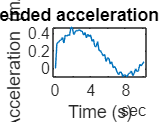

Fs = 6.25;
WaveTimeTable = table2timetable(WaveTable, 'SampleRate', Fs);
plot(WaveTimeTable.Time, WaveTimeTable.Heave);
xlabel("Time (s)");
ylabel("Acceleration (m/s^2)");
title("Detrended acceleration segment");

##  Plot Concatenated Data

Fs = 6.25;
WaveTimeTable = table2timetable(WaveTable, 'SampleRate', Fs);
plot(WaveTimeTable.Time, lowpass(WaveTimeTable.Heave, 10, Fs));

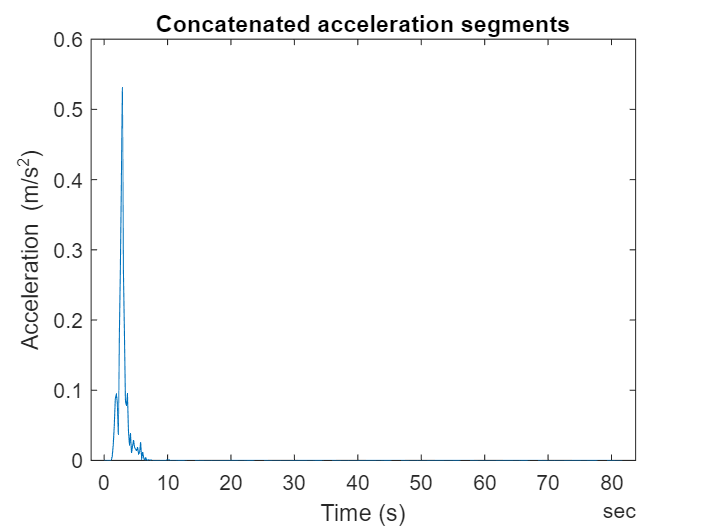

xlabel("Time (s)");
ylabel("Acceleration (m/s^2)");
title("Concatenated acceleration segments");

##  Plot FFT Data

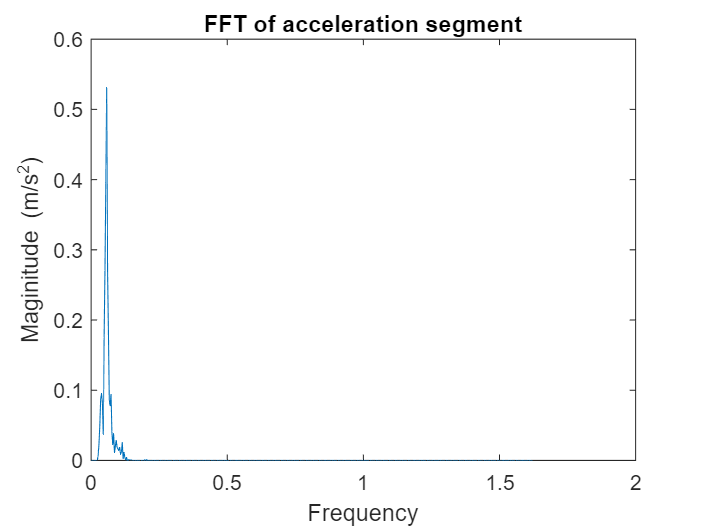


Fs = (104/16)/2; %104/16; %6.25; 
Nfft = 1024; 
f = Fs*(0:1:Nfft/2-1)'./Nfft;
WaveFFT = WaveTable.Heave(1:512);
plot(f, WaveFFT);
xlabel("Frequency");
ylabel("Maginitude (m/s^2)");
title("FFT of acceleration segment");


%f = Fs*(0:1:Nfft)'./Nfft

% WaveFFT = fft(WaveTable.Heave);
% WaveFFT = abs(WaveFFT.*(1/Fs));
% WaveFFT1Side = WaveFFT(1:Nfft/2+1);
% WaveFFT1Side(2:end-1) = 2*WaveFFT1Side(2:end-1);
% 
% plot(f, WaveFFT1Side);
% xlabel("Frequency");
% ylabel("Maginitude (m/s^2)");
% title("FFT of acceleration segment");

##  Plot Displacement Data

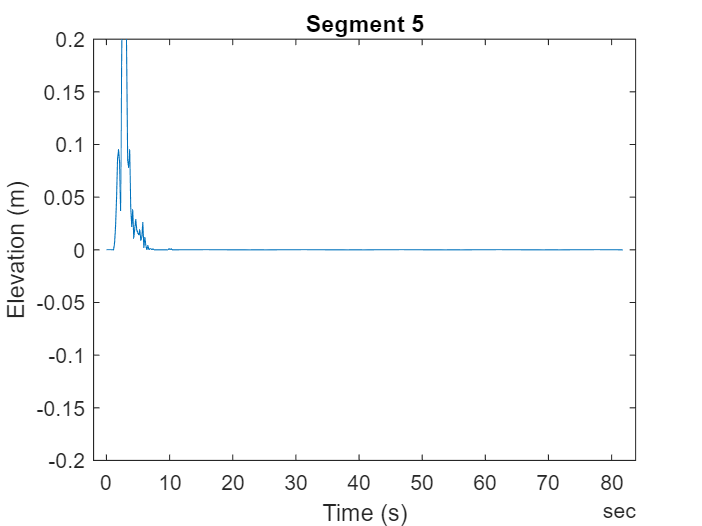

Fs = 6.25;
WaveTimeTable = table2timetable(WaveTable, 'SampleRate', Fs);
plot(WaveTimeTable.Time, WaveTimeTable.Heave);
    xlabel("Time (s)");
ylabel("Elevation (m)");
ylim([-0.2, 0.2]);
title("Segment 5");

## Plot PSD Data

Fs = (104/16)/2; %104/16; %6.25; 
Nfft = 1024; 
f = Fs*(0:1:Nfft/2-1)'./Nfft

f =          0
    0.0032
    0.0063
    0.0095
    0.0127
    0.0159
    0.0190
    0.0222
    0.0254
    0.0286


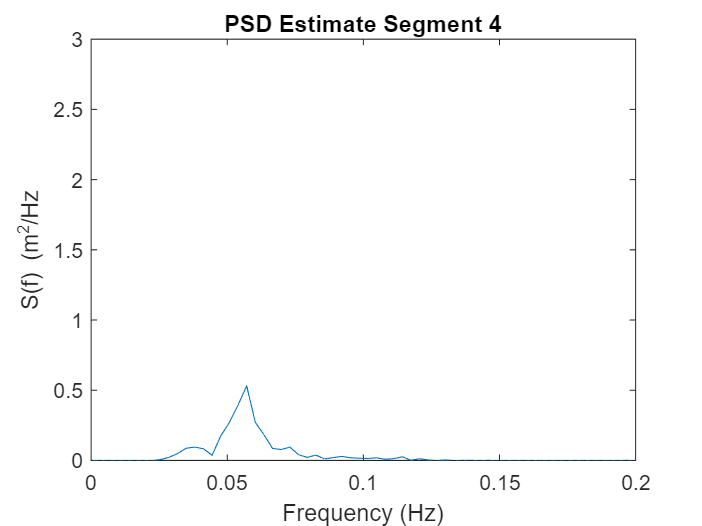


WavePSD = WaveTable.Heave(1:512);
plot(f, WavePSD);
xlabel("Frequency (Hz)");
xlim([0, 0.2]);
ylabel("S(f) (m^2/Hz");
ylim([0, 3]);
title("PSD Estimate Segment 4");